# AAC Clyde Space SS200 Characterization

These data used in this charcterization are consistent with the following information provided by the manufacterer: [https://www.aac-clyde.space/wp-content/uploads/2021/11/SS200.pdf.](https://www.aac-clyde.space/wp-content/uploads/2021/11/SS200.pdf.) The general product can be found at the following: [https://www.aac-clyde.space/what-we-do/space-products-components/adcs/ss200.](https://www.aac-clyde.space/what-we-do/space-products-components/adcs/ss200.) The following model is used as a base in developing the model to be used for evaluating performance.


$$I_j=\begin{cases} I_\text{max}(\vec{n_j} \cdot \vec{s}) & \text{for}\space\vec{n_j}\cdot\vec{s}\geq 0 \\ 0 & \text{for}\space\vec{n_j}\cdot\vec{s}\leq 0 \end{cases}$$
 

Source: *Fundamentals of Spacecraft Attitude Determination and Control*, pg. 133

- $\vec{n_j}$ is the unit vector of the normal of the sensor in the body frame

- $\vec{s}$ is the unit vector of the sun-direction in the body frame

We will use this model but with some additional modifications to better model the specifications provided for the sensor. The modifications are provided in the following list:

- Instead of the cutoff provided at 90 degrees off-incidence, this will be set to the field-of-view of the sun sensor

- No bias was provided by the manufacturer therefore a noise will be introduced into the actual measurement with amplitude consistent with the error provided by the manufacturer for the range of 45 degrees off-incidence

% Properties to be used below
fov = 110; % degrees
max_err_45_rng = 0.3 / 45; % degrees
max_sampl_rate = 100; % Hz

## Accuracy

Manufacturer specifications only provide maximum standard deviation of 0.3 degrees (1-sigma) within +/- 45 degrees off-incidence. This will be modelled as a random signal with maximum amplitude of 0.3 degrees over this region. For larger off-incident angles, a linear model will be used for worst case-error growth and is likely representative of actual error growth.

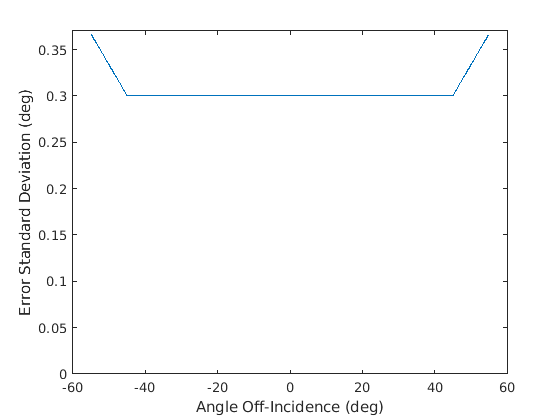

% Shows the maximum magnitude of the eror signal at varying degrees of the
% sensor off the incident angle. Error grows linearly past +/- 45 degrees

actual_ang = -fov/2:0.1:fov/2;

std_dev_ang = zeros(1, length(actual_ang)); % initializes for performance
for i = 1:length(actual_ang)
    std_dev_ang(i) = acc_error(actual_ang(i));
end

plot(actual_ang, std_dev_ang);
yl = ylim; % gets current y limits (to get max value)
ylim([0, yl(2)]); % changes the lower limit to be 0

xlabel("Angle Off-Incidence (deg)");
ylabel("Error Standard Deviation (deg)");

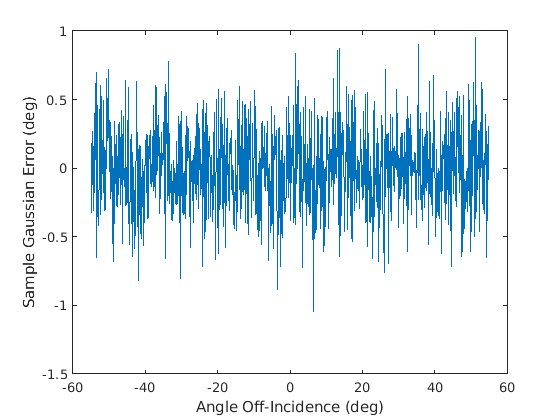


% Creates a random signal from random Gaussian sampling in accordance with the standard
% deviation present at each angle

rand_ang = zeros(1, length(actual_ang)); % initializes for performance
for i = 1:length(actual_ang)
    rand_ang(i) = normrnd(0, std_dev_ang(i)); % mean of 0
end

figure(2)
plot(actual_ang, rand_ang);

xlabel("Angle Off-Incidence (deg)");
ylabel("Sample Gaussian Error (deg)");

## Physical Modelling and Orientation

Although physical characteristics of the photodiodes, a similar mathematical notation will be used to represent the calculated error between the normal axis of the sensor and the direction of the sun. The notation can be extended generally to an arbitrary number of sensor normals in a given reference frame. The body frame will be used as the reference frame for this model.


$$S = \left[\matrix{ \hat{n_1} \dots \hat{n_m} }\right]^T \cdot \hat{s}$$


- $S$ is a vector containing the current dot products of each sensor normal with the actual sun direction

- $\hat{n_m}$ is a unit vector of a normal of the sun sensor

- $\hat{s}$ is the unit vector of the sun direction

% Chooses an arbitrary direction for the sun for this example
sun_dir = [2; 0.3; 0.7];
sun_dir_unit = sun_dir / norm(sun_dir)

sun_dir_unit =     0.9345
    0.1402
    0.3271



% To closely model our CubeSat, we will place a sun-sensor on each axis
sens_normals = [ 1 -1 0 0 0 0 ; 0 0 1 -1 0 0 ; 0 0 0 0 1 -1 ]

sens_normals =      1    -1     0     0     0     0
     0     0     1    -1     0     0
     0     0     0     0     1    -1



% Calculates the dot product of each normal with the sun direction. Note
% that for display purpose an additional transpose has been added to make
% the vector of sensor values a row vector
sens_dprods = (sens_normals' * sun_dir_unit)'

sens_dprods =     0.9345   -0.9345    0.1402   -0.1402    0.3271   -0.3271


The dot products can now be converted into angles of the sun vector off the normal axis of the sensor. Gaussian error is added to the these angles prior to conversion back to a dot product. This dot product form allows a more convenient method of providing a lower cutoff value where all angles outside the field-of-view will be dropped and will read as 0.

% Calculates the angles of the sun off the normal axis
sens_angs = rad2deg(acos(sens_dprods))

sens_angs =    20.8463  159.1537   81.9417   98.0583   70.9078  109.0922



sens_noise = zeros(1, length(sens_angs)); % Gaussian noise in degrees
for i = 1:length(sens_angs_deg)
    sens_noise(i) = normrnd(0, acc_error(sens_angs_deg(i)));
end

sens_noise % displays output

sens_noise =     0.3598   -0.5868    1.2838   -0.1369    0.4181   -1.6421



sens_angs_noisy = sens_angs + sens_noise

sens_angs_noisy =    21.2061  158.5669   83.2255   97.9214   71.3260  107.4501



sens_dprods_noisy = cos(deg2rad(sens_angs_noisy))

sens_dprods_noisy =     0.9323   -0.9308    0.1180   -0.1378    0.3202   -0.2999



lower_thres = cos(deg2rad(fov / 2)); % cuts values off if outside sun sensor fov
sens_readouts = sens_dprods_noisy .* (sens_dprods_noisy >= lower_thres) % outputs

sens_readouts =     0.9323         0         0         0         0         0


Note that this is the 

## Functions

function [std_dev] = acc_error(ang)
    % Calculates the maximum standard deviation of the error at a given 
    % angle over the range of the field-of-view of the sun-sensor

    % Maximum standard deviation over the valid angle range of +/- 45 degrees
    acc_std_dev_vrange = 0.3; % degree

    % Linear coefficient of error as function of off-incidient angle
    acc_coeff_lrange = 0.3 / 45; % deg/deg

    off_incident_ang = abs(ang);
    if off_incident_ang <= 45
        std_dev = acc_std_dev_vrange;
    else
        std_dev = acc_coeff_lrange * abs(off_incident_ang);
    end
end